# **Report about CSI and its utility in indoor localization**

**Liu Jun, 2017-08-07**

Channel State Information is essential for OFDM communication. By sending a pre-defined traning sequence, channel state informaion could be obtained from the received side and could be used to restore the received signal distorted by multipath, doppler effect, etc. Indoor localization is widely studied recently, lab project like Spot-Fi from Stanford, Chronos from MIT, Splicer from NTU, etc are published. Some are said to be decimeter-level in simple lab environment. 

However when trying the implmentation of Sport-Fi, It is found really difficult to correctly estimate AoA and ToF. The technology is currently not ready for commercial use.

In this report, I will summarize the current findings related to CSI.

## Loading CSI data

Here we load CSI data from one measurement, with Rx-to-Tx distance 3.2 meters, LOS angle 45 degree, measurement on August 4, 2017.

clear
close all
% load csi_trace
%%%%%%%%%%
raw_csi_trace = read_bf_file('csi-data/csi-20170804-320-7-45-2.dat');
% csi_trace = read_bf_file('csi-0605-2.dat');
%% load csi_trace
% csi_trace = csi_trace;
%%%%%%%%%%
sample_idxes = 2017:2116; % take a period as an example
sample_csi_trace= raw_csi_trace(sample_idxes);
idx = 1;
csi_frame = sample_csi_trace{idx};
csi_frame_2 = sample_csi_trace{idx+1};
csi_matrix = squeeze(csi_frame.csi(1,:,:));
csi_matrix_2 = squeeze(csi_frame_2.csi(1,:,:));


## **Inspect the csi data**

Plot Basic amplitude and phases

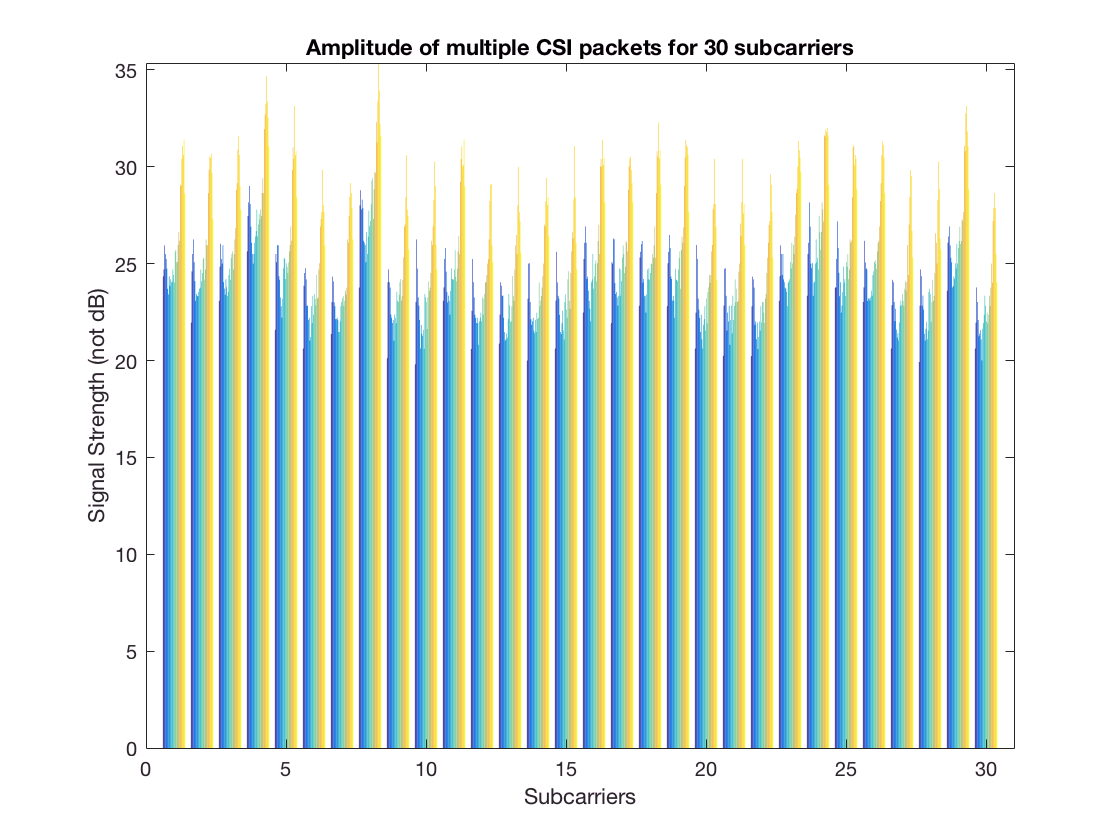


csi_matrix_for_stability_plot = zeros(length(sample_csi_trace),3,30);
for i=1:length(sample_csi_trace)
   csi_matrix_for_stability_plot(i,:,:) = squeeze(sample_csi_trace{i}.csi(1,:,:));
end

amp_multi = abs(csi_matrix_for_stability_plot);
figure(11), bar(squeeze(amp_multi(1:30,1,:)))
axis([0 31 -inf inf])
title('Amplitude of multiple CSI packets for 30 subcarriers')
xlabel('Subcarriers')
ylabel('Signal Strength (not dB)')

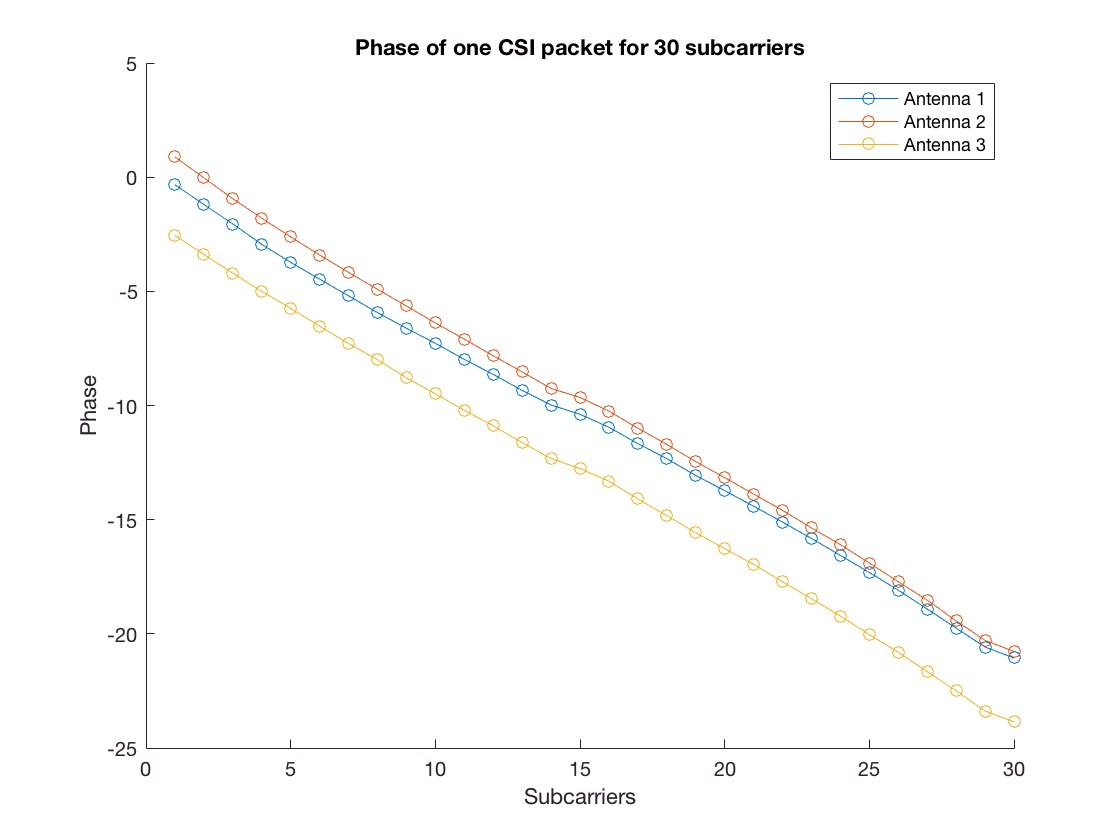


amp = abs(csi_matrix);
fi = angle(csi_matrix);
fii = csi_phase_smooth(fi,csi_frame.Nrx);

figure(12),clf
hold on
x_sc = 1:30;
plot(x_sc,squeeze(fii(1,:)),'-o') 
plot(x_sc,squeeze(fii(2,:)),'-o')
plot(x_sc,squeeze(fii(3,:)),'-o')
legend('Antenna 1','Antenna 2','Antenna 3');
title('Phase of one CSI packet for 30 subcarriers')
xlabel('Subcarriers')
ylabel('Phase')
hold off

## **Extend 30 subcarrier to 57 subcarrier by interpolation**

Reconstruct the whole spectrum of received signal (also impulse response)

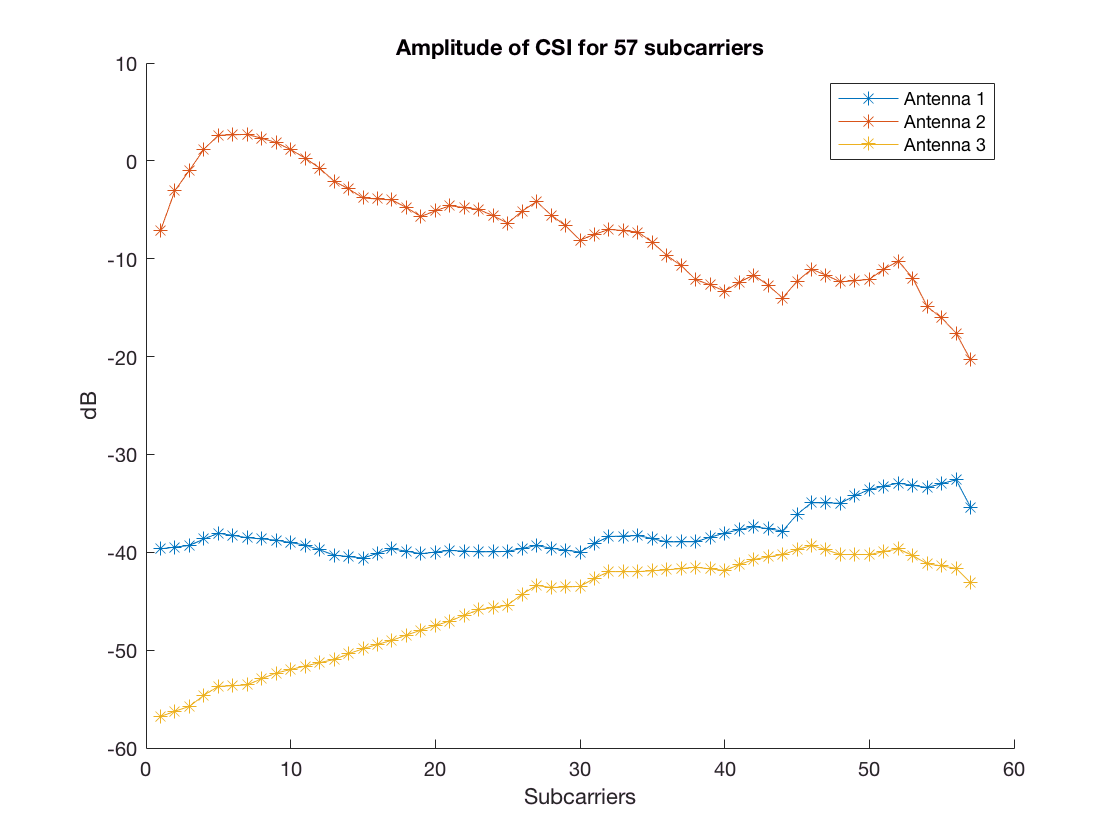

e_csi = csi_extend_57(csi_matrix);
x_sc = 1:57;
amp = abs(e_csi);
amp = amp - 44 - csi_frame.agc; % check get_total_rss for more information

% plot amplitude in dB scale
figure(21),clf
hold on
plot(squeeze(amp(1,:)),'-*')
plot(squeeze(amp(2,:)),'-*')
plot(squeeze(amp(3,:)),'-*')
legend('Antenna 1','Antenna 2','Antenna 3');
hold off
title('Amplitude of CSI for 57 subcarriers')
xlabel('Subcarriers')
ylabel('dB')

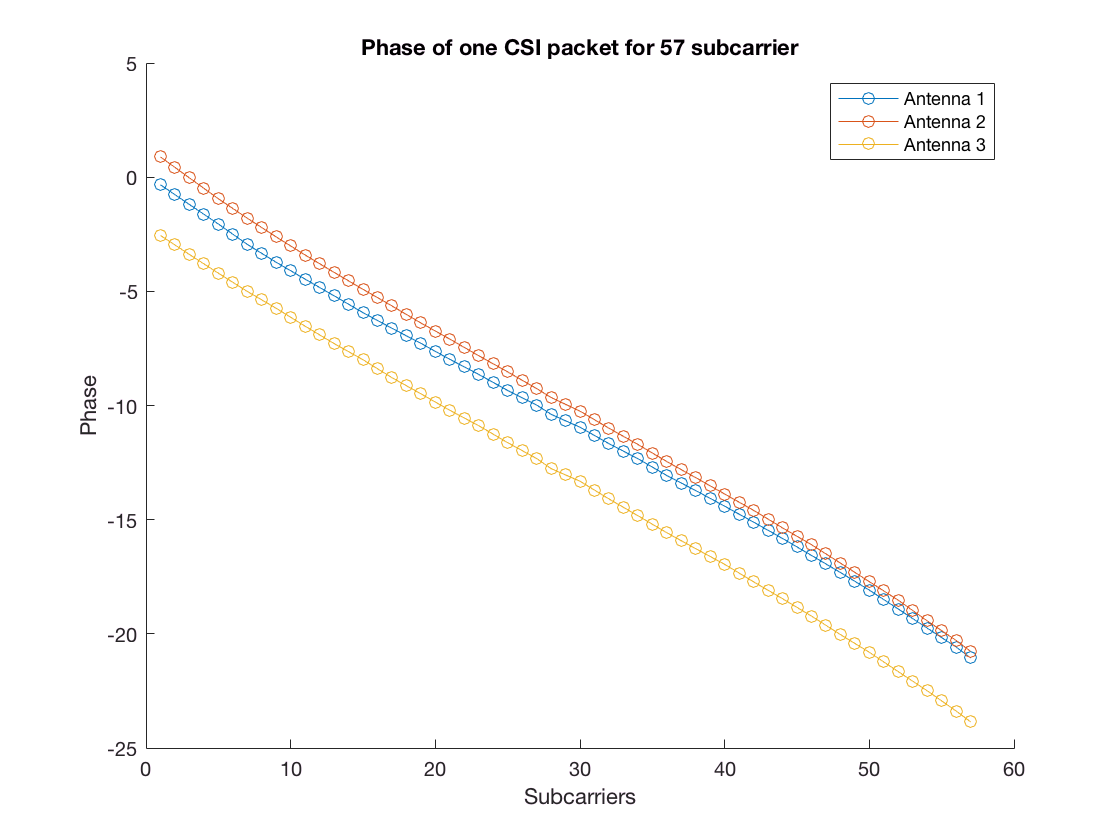


fi = angle(e_csi);
fii = csi_phase_smooth(fi,csi_frame.Nrx);


figure(22),clf
hold on
plot(x_sc,squeeze(fii(1,:)),'-o') 
plot(x_sc,squeeze(fii(2,:)),'-o')
plot(x_sc,squeeze(fii(3,:)),'-o')
legend('Antenna 1','Antenna 2','Antenna 3');
title('Phase of one CSI packet for 57 subcarrier')
xlabel('Subcarriers')
ylabel('Phase')
hold off

## Sanitizing ToF Estimates

Sanitizing ToF according to Spot-Fi. This is not used in real implmentation, because it will bring peak of ToF back to 0 strangly (need further study later).

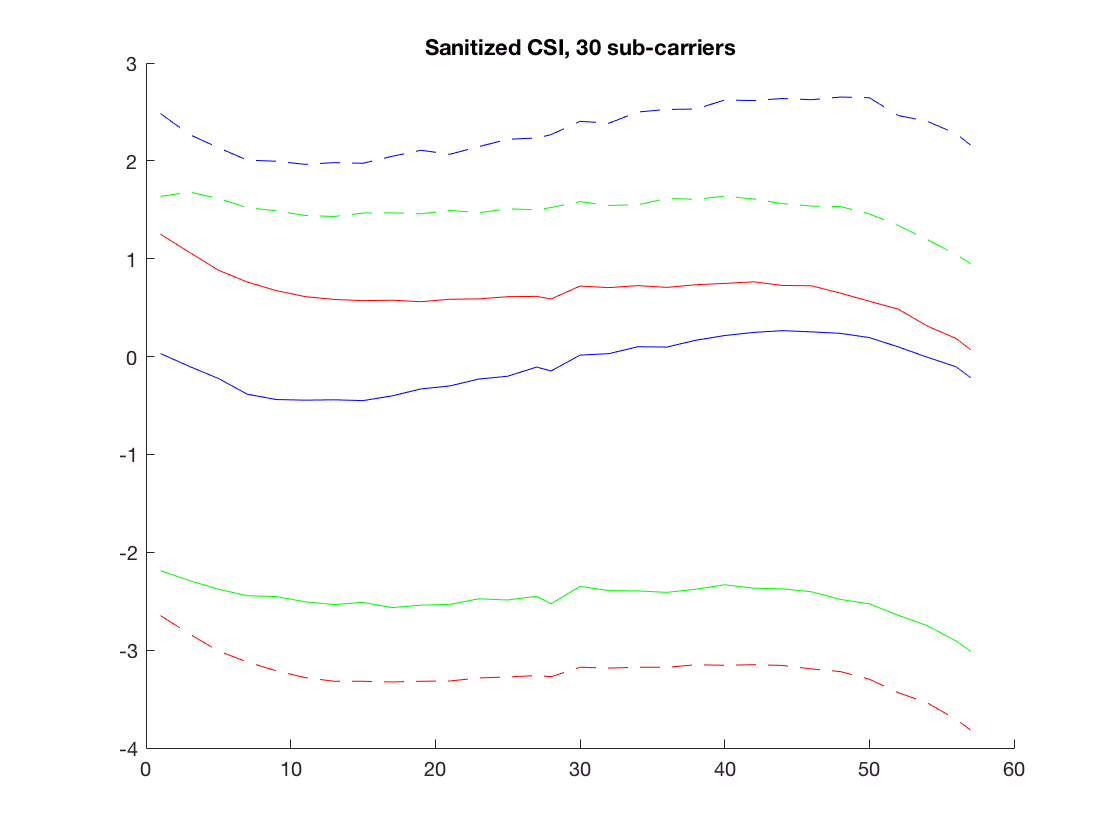

x_sc = 1:57;

e_csi = csi_extend_57(csi_matrix);
amp = abs(e_csi);
fi = angle(e_csi);
fii = csi_phase_smooth(fi,csi_frame.Nrx);

a = polyfit([x_sc-1 x_sc-1 x_sc-1],[fii(1,:) fii(2,:) fii(3,:)],1);

e_csi_2 = csi_extend_57(csi_matrix_2);
amp_2 = abs(e_csi_2);
fi_2 = angle(e_csi_2);
fii_2 = csi_phase_smooth(fi_2,csi_frame_2.Nrx);
a_2 = polyfit([x_sc-1 x_sc-1 x_sc-1],[fii_2(1,:) fii_2(2,:) fii_2(3,:)],1);


figure(31),clf
a(2) = 0;
a_2(2) = 0;
hold on
plot(x_sc,fii(1,:) - polyval(a,x_sc,1),'b-')
plot(x_sc,fii(2,:) - polyval(a,x_sc,1),'r-')
plot(x_sc,fii(3,:) - polyval(a,x_sc,1),'g-')

plot(x_sc,fii_2(1,:) - polyval(a_2,x_sc,1),'b--')
plot(x_sc,fii_2(2,:) - polyval(a_2,x_sc,1),'r--')
plot(x_sc,fii_2(3,:) - polyval(a_2,x_sc,1),'g--')
hold off
title('Sanitized CSI, 30 sub-carriers')


% This part is currently not used for data progress
% fi = fii - [polyval(a,x_sc,1); polyval(a,x_sc,1); polyval(a,x_sc,1)];
% [csi_matrix_real,csi_matrix_imag] = pol2cart(fi,amp);
% csi_matrix = csi_matrix_real + 1j*csi_matrix_imag;

## Smoothed CSI Matrix

Construct smoothed CSI matrix according to Spot-Fi by taking sub-carriers as psedo antennas to extend antenna amount for MUSIC algorithm. A basic assumption of MUSIC algorithm is, the amount of antennas must be greater than that of multipaths.

% idx = 3;
% csi_matrix(:,:,idx);
e_csi = csi_extend_57(csi_matrix);
smoothed_csi = zeros(30,86);

for i=1:15
    smoothed_csi(i,:) = [e_csi(1,i:i+42),e_csi(2,i:i+42)]; 
end

for i=16:30
    smoothed_csi(i,:) = [e_csi(2,i-15:i+27),e_csi(3,i-15:i+27)]; 
end

## MUSIC algorithm, calculating noise space

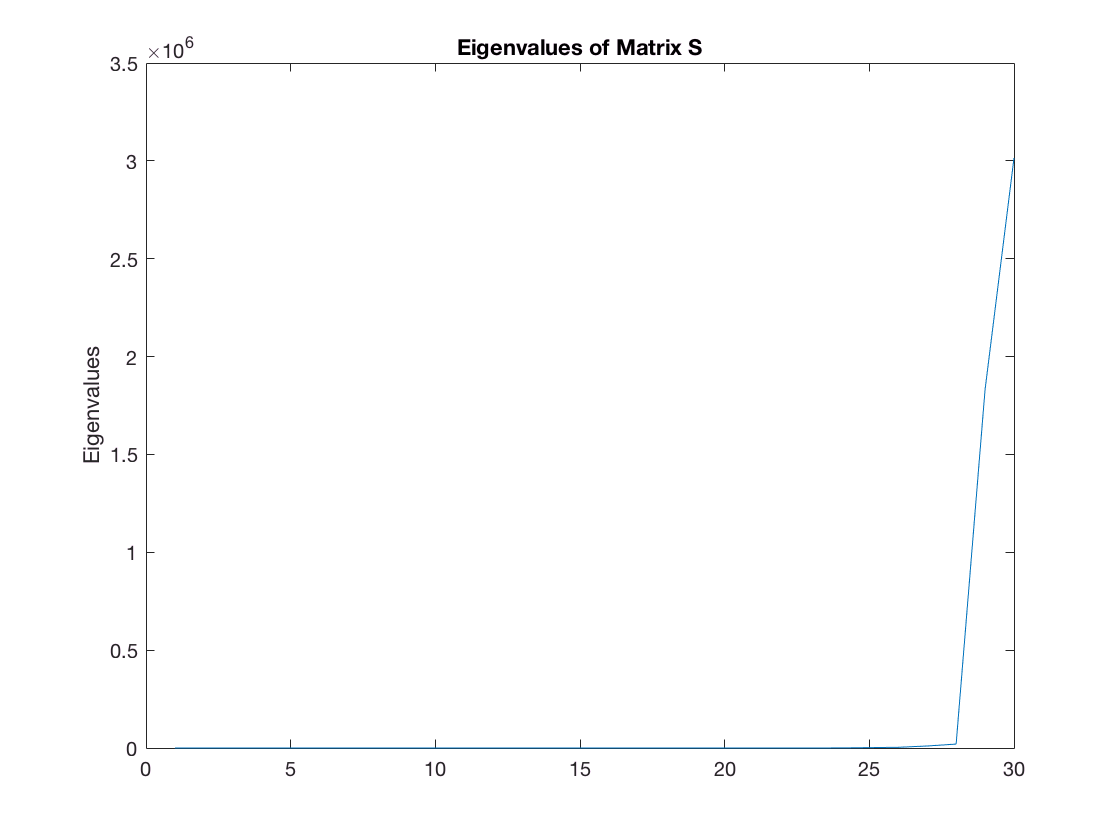

MUSIC_S = smoothed_csi * smoothed_csi';

[EigenVector1, EigenValue1] = eig(MUSIC_S);
EigenValueList1 = diag(EigenValue1);

[~, order] = sort(EigenValueList1);

EigenVector = EigenVector1(:,order);

figure(51);
plot(EigenValueList1)
title('Eigenvalues of Matrix S')
ylabel('Eigenvalues')

## **MUSIC algorithm, extracting steering matrix**

M sensors, D multipath, N zero eigenvalues

M = N + D

Empirically, D=6~8 (significant reflectors according to SpotFi, Chapter 3.1)


EigenValueThreshold = max(EigenValueList1) * 1e-4;
NoiseVectorIdx=find(EigenValueList1<EigenValueThreshold);

En = EigenVector(:,NoiseVectorIdx);

degrees = -90:0.5:90; % linspace
[~,deg_tot] = size(degrees);
tofs = 1e-9:1e-9:300e-9;
[~,tof_tot] = size(tofs);

c = 3e8; % speed of light
f = 2.412e9; % central frequency, all on channel 1
fs = 312.5e3; % frequency diff between consecutive subcarriers
d = 0.07;  % 7 cm between antennas
SP = zeros(deg_tot,tof_tot);

tic
for deg_idx = 1:deg_tot
    deg = degrees(deg_idx);
    theta = deg*pi/180;
    phi = exp(-1j*2*pi*d*sin(theta)*f/c);
    for tof_idx = 1:tof_tot
        tof = tofs(tof_idx);
        omega = exp(-1j*2*pi*fs*tof);
        half = omega.^((0:14)');
        a = [half;
            half.*phi];

        % SP(deg_idx,tof_idx)=(a'*a)/(a'*En*En'*a);
        SP(deg_idx,tof_idx)=1/(a'*En*En'*a);
    end
end
toc

Elapsed time is 138.722388 seconds.


## **Find most likely AoA and ToF**

Peeks of $P_{MU}$ represent a pair of AoA and ToF to a possible multipath. 

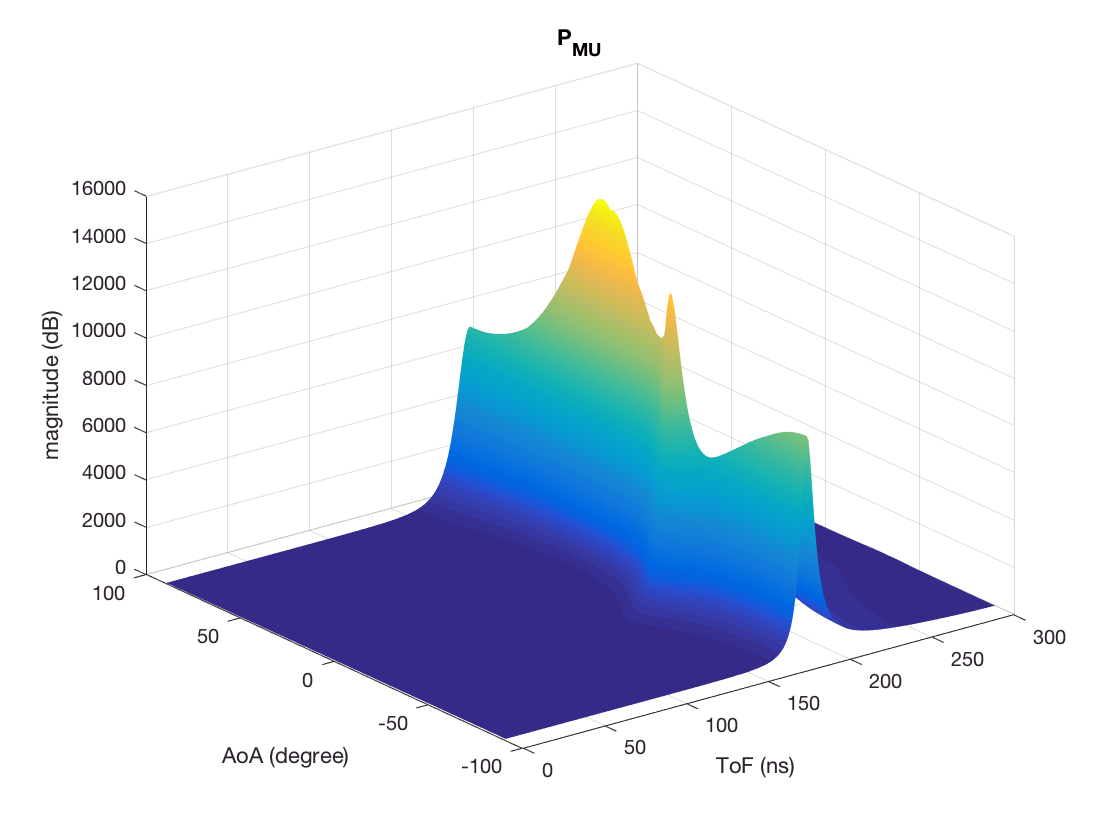

Pmu=abs(SP);
Pmu_max=max(Pmu);
% Pmu_db = 10*log10(Pmu./Pmu_max);

figure(71)
surf(tofs*1e9,degrees,Pmu)
xlabel('ToF (ns)')
ylabel('AoA (degree)') 
zlabel('magnitude (dB)')
title('P_{MU}')
grid on  
shading interp;



Pmu_mirror = [Pmu; flipud(Pmu)];
maxima = find_maxima(Pmu_mirror);
rads = degrees'*pi/180;

for k=1:size(maxima,1)
    if maxima(k,1)<=length(rads)
        AoA = rads(maxima(k,1))*180/pi;
        ToF = maxima(k,2);
        fprintf('   AoA=%d  ToF=%d ns\n',ceil(AoA),ToF);
    end
end

   AoA=-28  ToF=173 ns


   AoA=-14  ToF=180 ns


   AoA=12  ToF=183 ns


   AoA=18  ToF=184 ns


## **An overall implementation for AoA estimation**

In this implementation, it takes from dataset No. 2017 to dataset No.2047. Ideally, the estimations should be stable for a fixed emmiter and receiver. However, ToF estimation seems vary a lot, and AoA seems hard to estimate.

csi_trace = read_bf_file('csi-data/csi-20170804-320-7-45-2.dat'); % 72000pkt in 45s
% aoas = zeros(1,length(csi_good))
% csi_trace = csi_trace_30;
% load mat_csi_30_simulated_1.mat
% csi_trace = csi_trace_30;

dataset = [];
countdown = 30;

for idx=2017:length(csi_trace)
    if csi_trace{idx}.Nrx == 3
        countdown = countdown - 1;
        for tx=1:1 % csi_trace{idx}.Ntx
            e_csi = csi_extend_57(csi_trace{idx}.csi(tx,:,:));
            % do estimation
            [tofs, rads, Pmu] = csi_find_aoa_spotfi_sp1(csi_trace{idx},e_csi);
%             figure(10);
%             surf(tofs*1e9,rads*180/pi,Pmu)
%             xlabel('ToF (ns)')
%             ylabel('AoA (degree)') 
%             zlabel('magnitude (dB)')
%             grid on  
%             shading interp;
%             drawnow;
%             pause(0.8);
            Pmu_mirror = [Pmu; flipud(Pmu)];
            maxima = find_maxima(Pmu_mirror);
            fprintf('idx %d: \n',idx);
            for k=1:size(maxima,1)
                if maxima(k,1)<=length(rads)
                    AoA = rads(maxima(k,1))*180/pi;
                    ToF = maxima(k,2);
                    fprintf('   AoA=%d  ToF=%d ns\n',ceil(AoA),ToF);
                    dataset(end+1,:) = [AoA,ToF,Pmu(maxima(k,1),maxima(k,2))];
    %             else
    %                 fprintf('idx %d: miss\n',idx);
                end
            end
        end
    end
    if countdown <= 0
        break;
    end
end

idx 2017: 


   AoA=-28  ToF=173 ns


   AoA=-14  ToF=180 ns


   AoA=12  ToF=183 ns


   AoA=18  ToF=184 ns


idx 2018: 


   AoA=90  ToF=188 ns


   AoA=-7  ToF=191 ns


   AoA=-3  ToF=192 ns


idx 2019: 


   AoA=-42  ToF=197 ns


   AoA=90  ToF=198 ns


   AoA=12  ToF=206 ns


idx 2020: 


   AoA=36  ToF=189 ns


   AoA=-12  ToF=197 ns


idx 2021: 


   AoA=37  ToF=179 ns


   AoA=-10  ToF=189 ns


idx 2022: 


   AoA=39  ToF=144 ns


idx 2023: 


   AoA=90  ToF=152 ns


   AoA=-44  ToF=153 ns


   AoA=-12  ToF=159 ns


   AoA=-4  ToF=160 ns


idx 2024: 


   AoA=7  ToF=49 ns


   AoA=12  ToF=50 ns


   AoA=18  ToF=51 ns


idx 2025: 


   AoA=-3  ToF=160 ns


   AoA=90  ToF=163 ns


idx 2026: 


   AoA=-75  ToF=146 ns


   AoA=54  ToF=146 ns


idx 2027: 


   AoA=-46  ToF=41 ns


   AoA=90  ToF=42 ns


   AoA=18  ToF=51 ns


idx 2028: 


   AoA=90  ToF=157 ns


   AoA=-3  ToF=158 ns


idx 2029: 


   AoA=-17  ToF=152 ns


   AoA=6  ToF=161 ns


   AoA=14  ToF=162 ns


idx 2030: 


   AoA=-46  ToF=148 ns


   AoA=90  ToF=148 ns


idx 2031: 


   AoA=-62  ToF=157 ns


   AoA=63  ToF=157 ns


   AoA=-4  ToF=163 ns


idx 2032: 


   AoA=-45  ToF=197 ns


   AoA=90  ToF=197 ns


idx 2033: 


   AoA=-48  ToF=170 ns


   AoA=90  ToF=170 ns


idx 2034: 


   AoA=-59  ToF=179 ns


   AoA=67  ToF=179 ns


   AoA=-31  ToF=182 ns


   AoA=-2  ToF=185 ns


idx 2035: 


   AoA=1  ToF=183 ns


   AoA=14  ToF=184 ns


   AoA=25  ToF=185 ns


   AoA=31  ToF=186 ns


idx 2036: 


   AoA=28  ToF=158 ns


   AoA=30  ToF=159 ns


   AoA=-79  ToF=161 ns


   AoA=53  ToF=161 ns


   AoA=90  ToF=162 ns


   AoA=-19  ToF=163 ns


idx 2037: 


   AoA=-39  ToF=136 ns


   AoA=90  ToF=136 ns


idx 2038: 


   AoA=14  ToF=156 ns


idx 2039: 


   AoA=-14  ToF=181 ns


   AoA=35  ToF=191 ns


idx 2040: 


   AoA=28  ToF=201 ns


idx 2041: 


   AoA=-2  ToF=177 ns


   AoA=90  ToF=182 ns


idx 2042: 


   AoA=90  ToF=51 ns


   AoA=-17  ToF=54 ns


idx 2043: 


   AoA=37  ToF=152 ns


   AoA=-10  ToF=162 ns


idx 2044: 


   AoA=26  ToF=153 ns


   AoA=27  ToF=154 ns


   AoA=29  ToF=155 ns


   AoA=34  ToF=156 ns


   AoA=-57  ToF=159 ns


   AoA=70  ToF=159 ns


idx 2045: 


   AoA=24  ToF=191 ns


idx 2046: 


   AoA=-27  ToF=156 ns


   AoA=90  ToF=157 ns


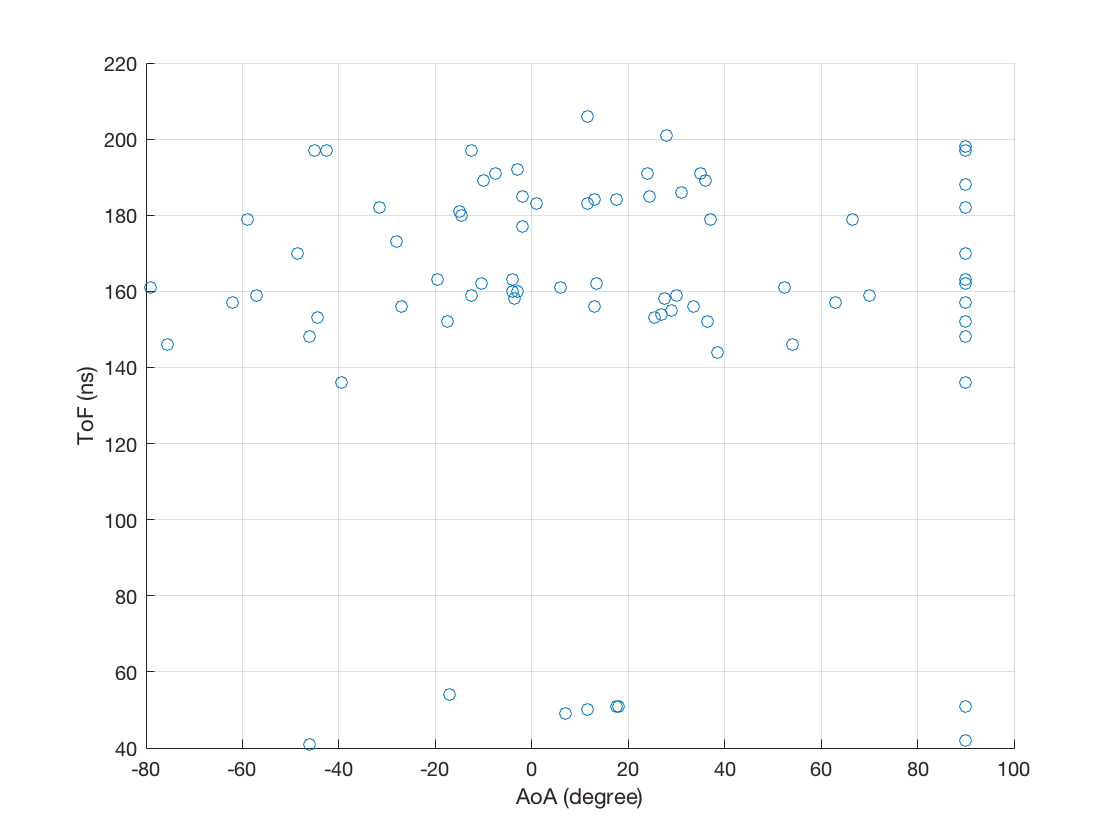


figure(81);
scatter(dataset(:,1),dataset(:,2));
xlabel('AoA (degree)') 
ylabel('ToF (ns)')
grid on  

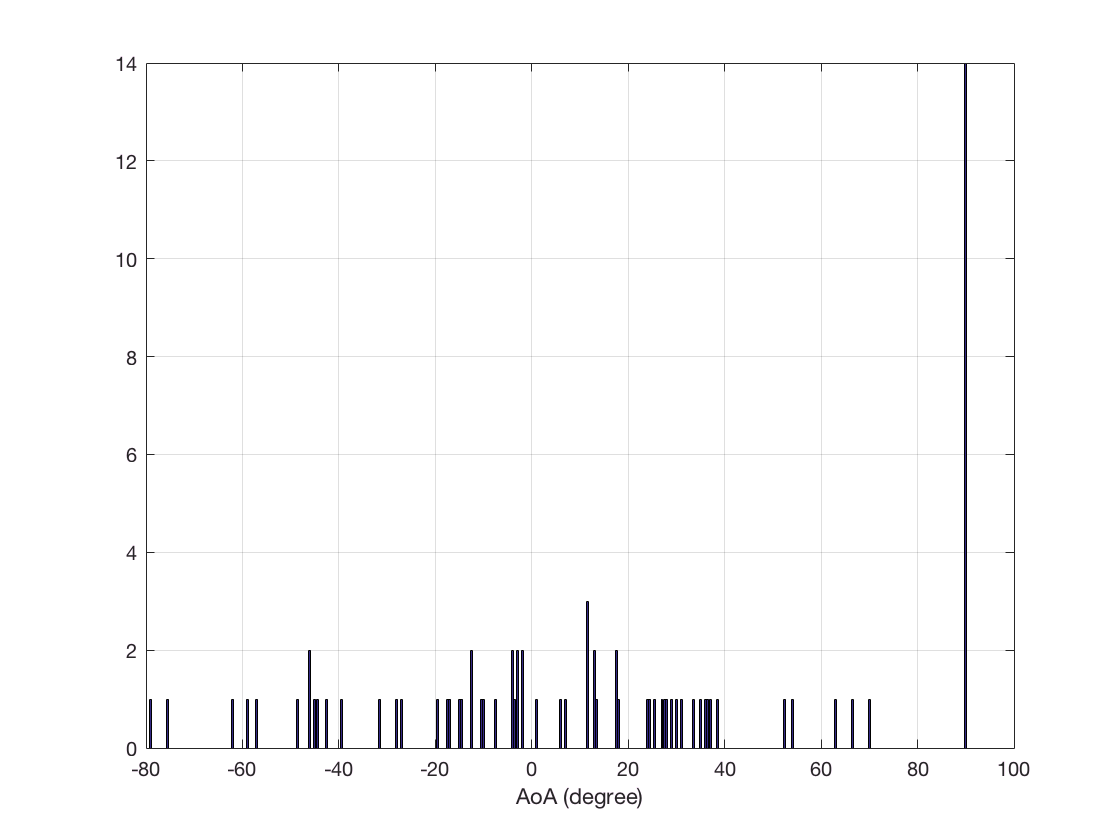


figure(82);
statistic = tabulate(dataset(:,1));
bar(statistic(:,1),statistic(:,2));
xlabel('AoA (degree)') 
ylabel('')
grid on  


save csi-20170804-320-7-45-2-result-2017-2116.mat dataset

## **Additional: Simulation**

A brief simulation.

   AoA=-55  ToF=51 ns


   AoA=73  ToF=51 ns


   AoA=30  ToF=80 ns


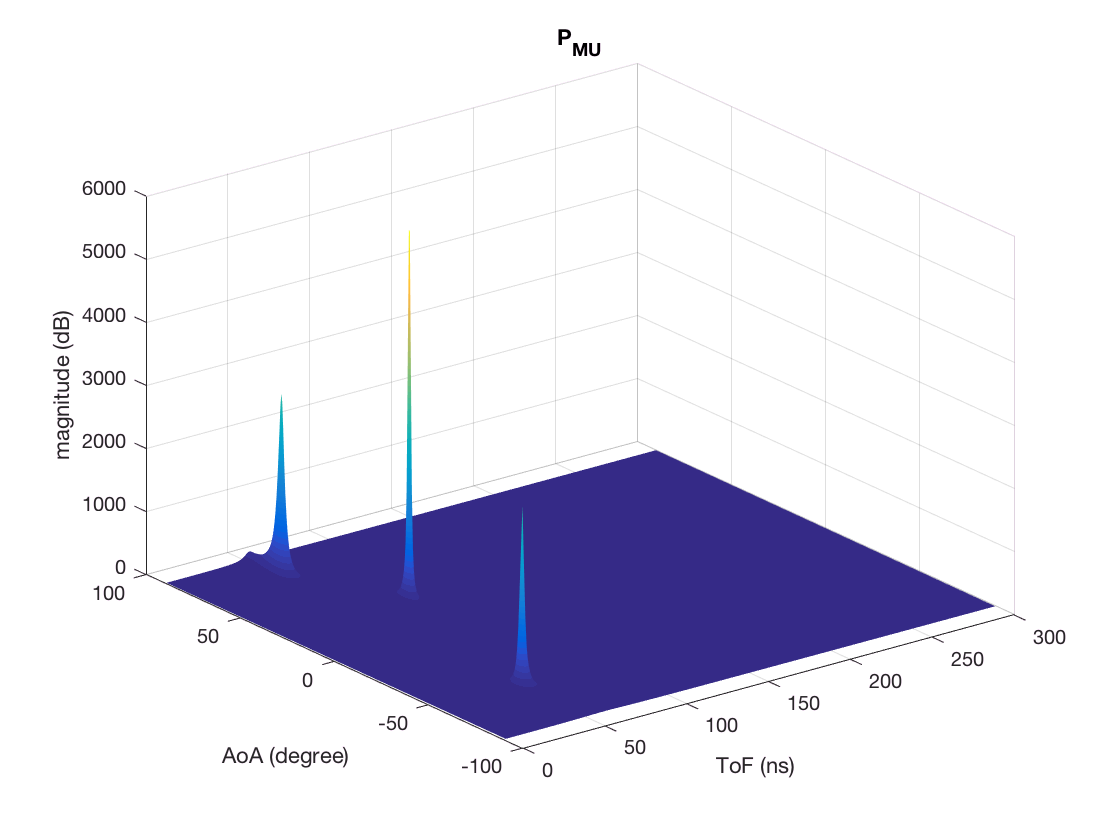

%% Basic simulation for 3 antennas

% Number of Paths D=8
D = 2; 
% incident angle and weight for each path 
incident_angle = [72 30];

num_of_pkt = 1;
% csi_simulated_pkt = zeros(num_of_pkt,3,57);

for pkt=1:num_of_pkt

    incident_attenuation = (randn([1 D])+1j*(randn([1 D])));
    % incident_attenuation = [10+0.2j 3-0.5j];
    % incident_attenuation = [10 20 30 40 50 60 70 80];
    % set 45 degree as the major direction
    %incident_attenuation(3) = 5;
    % set time of flight, 1ns~0.3m, 10ns~3m, 100ns~30m
    % tof = randi([1 50],[D 1]) * 1e-9;
    % tof = [200 100 120 130 140 150 160 170]' .* 1e-9;
    tof = [50 80]' .* 1e-9;
    % tof(3) = 15e-9;
    
    % % Number of Paths D=2
    % D = 2; 
    % M = 3;
    % % Set incident angle and weight for each path 
    % incident_angle = [17 20];
    % incident_attenuation = (randi([2 6],[1 2])+1j*(randi([2 4],[1 2])));
    % % set 45 degree as the major direction
    % % incident_attenuation(2) = 30 + 30j;
    % % set time of flight, 1ns~0.3m, 10ns~3m, 100ns~30m
    % tof = randi([8 40],[1 2]) * 1e-9;
    % % tof(3) = 20e-9;
    
    %% Fomulate steering matrix and incident quanties, given by the number of multipath
    c = 3e8; % speed of light
    f = 2.412e9; % central frequency
    fs = 312.5e3; % 312.5 kHz
    d = 0.07; % the minimal distance in between is 0.012 
    twopi = 2*pi;
    deg2rad = pi/180;
    phiD = exp(-1j*twopi*d*sin(incident_angle*deg2rad)*f/c);  % 1*D
    omega = exp(-1j*twopi*fs*tof);   % D*1
    
    csi_cell.timestamp_low = 4;
    csi_cell.bfee_count = 1;
    csi_cell.Nrx = 3;
    csi_cell.Ntx = 1;
    csi_cell.rssi_a = 39;
    csi_cell.rssi_b = 36;
    csi_cell.rssi_c = 33;
    csi_cell.noise = -78;
    csi_cell.agc = 24;
    csi_cell.perm = [1 2 3];
    csi_cell.rate = 8454;
    csi_cell.csi = zeros(1,3,30);
    
    A = [ones(1,D)
        phiD
        phiD.^2];
    
    F = zeros(D,57);
    FF = omega.^(0:56);
    
    for row=1:D
       F(row,:) = incident_attenuation(row).*FF(row,:);    
    end
    
    %% Simulate CSI measurements
    
    X1 = A*F;
    snr = 25;
    X  = awgn(X1,snr,'measured');

    %% Spoi-fi solution
    csi_simulated = X;
    % csi_find_aoa_spotfi_sp1 is the same as stated in MUSIC algorithm 
    [tofs, rads, Pmu] = csi_find_aoa_spotfi_sp1(csi_cell,csi_simulated);
    
    figure(91);
    surf(tofs*1e9,rads*180/pi,Pmu)
    xlabel('ToF (ns)')
    ylabel('AoA (degree)') 
    zlabel('magnitude (dB)')
    title('P_{MU}')
    shading interp;
    Pmu_mirror = [Pmu; flipud(Pmu)];
    maxima = find_maxima(Pmu_mirror);
    for k=1:size(maxima,1)
        if maxima(k,1)<=length(rads)
            AoA = rads(maxima(k,1))*180/pi;
            ToF = maxima(k,2);
            fprintf('   AoA=%d  ToF=%d ns\n',ceil(AoA),ToF);
        end
    end
end